clear; clc;

%% Constants for guest trimer aggregation (known)
KG2 = 0.14;  % M^-1
KG3 = 61.6;  % M^-2

%% Example Titration Data
Gtot = [0.0001794, 0.0007659, 0.0013317, 0.00218385, 0.0032637, 0.0041124, 0.00507495]' * 1e-0;  % Guest total in M
Htot = [0.00023, 0.00023, 0.00023, 0.00023, 0.00023 ,0.00023, 0.00023]' * 1e-0;       % Host total in M
delta_exp = [8.5591, 8.5583 ,8.5571, 8.5557 ,8.5542, 8.5530, 8.5518]';  % Replace with real NMR data

%% Initial Guess: [logK1, logK2, δ_H, δ_HG, δ_HG2]
params0 = [2, 3, 8.5, 8.5, 8.5];
lb = [0, 0, 7, 7, 7];
ub = [6, 6, 8.8, 8.8, 8.8];

%% Fit
options = optimoptions('lsqcurvefit','Display','iter','TolFun',1e-9,'TolX',1e-9);
[params_fit,~,~,~,~,~,~] = lsqcurvefit( ...
    @(p,x) model_host_shift_HG2_Gagg(p,x,KG2,KG3), ...
    params0, [Htot Gtot], delta_exp, lb, ub, options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          6         0.0216845                           0.0736
     1         12       0.000568238        0.133785           0.0102      
     2         18        1.9229e-06       0.0752257         0.000377      
     3         24       9.11774e-07        0.123218          0.00134      
     4         30       7.54726e-08       0.0225944         0.000161      
     5         36        5.7128e-08       0.0875787          1.9e-05      
     6         42        4.9746e-08        0.062031         1.17e-05      
     7         48       4.74312e-08       0.0693296         1.29e-05      
     8         54       4.30076e-08       0.0454265         4.07e-07      
     9         60       4.30076e-08        0.617149         4.07e-07      
    10         66       4.30076e-08        0.154287         4.07e-07      
    11         72       4.30076e-08      

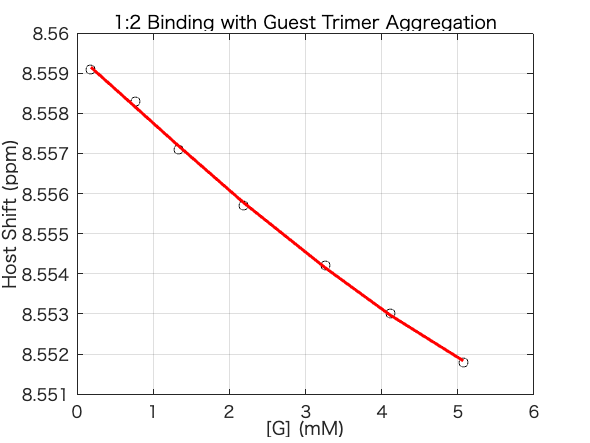


%% Plot
delta_fit = model_host_shift_HG2_Gagg(params_fit,[Htot Gtot],KG2,KG3);
figure;
plot(Gtot*1e3, delta_exp, 'ko'); hold on;
plot(Gtot*1e3, delta_fit, 'r-', 'LineWidth', 2);
xlabel('[G] (mM)'); ylabel('Host Shift (ppm)');
title('1:2 Binding with Guest Trimer Aggregation');
grid on;


fprintf('Fitted log10(K1) = %.2f\n', params_fit(1));

Fitted log10(K1) = 1.82


fprintf('Fitted log10(K2) = %.2f\n', params_fit(2));

Fitted log10(K2) = 2.35



% Calculate R-squared
SS_res = sum((delta_exp - delta_fit).^2);
SS_tot = sum((delta_exp - mean(delta_exp)).^2);
R_squared = 1 - (SS_res / SS_tot);

% Display R-squared
fprintf('R-squared: %.6f\n', R_squared);

R-squared: 0.999047


function F = system_eqs_HG2_G_agg(x, Htot, Gtot, KG2, KG3, K1, K2)
    % x = [H, G, HG, HG2, G2, G3]
    H = x(1); G = x(2); HG = x(3); HG2 = x(4);
    G2 = x(5); G3 = x(6);

    F(1) = G2 - KG2 * G^2;
    F(2) = G3 - KG3 * G^3;
    F(3) = HG - K1 * H * G;
    F(4) = HG2 - K2 * HG * G;

    % Mass balances
    F(5) = Htot - (H + HG + HG2);
    F(6) = Gtot - (G + 2*G2 + 3*G3 + HG + 2*HG2);
end

function delta_obs = model_host_shift_HG2_Gagg(params, xdata, KG2, KG3)
    K1 = 10^params(1);
    K2 = 10^params(2);
    delta_H = params(3);
    delta_HG = params(4);
    delta_HG2 = params(5);

    N = size(xdata,1);
    delta_obs = zeros(N,1);

    for i = 1:N
        Ht = xdata(i,1);
        Gt = xdata(i,2);

        x0 = [Ht, Gt, 1e-6, 1e-6, 1e-6, 1e-6];  % [H G HG HG2 G2 G3]
        sol = fsolve(@(x) system_eqs_HG2_G_agg(x, Ht, Gt, KG2, KG3, K1, K2), ...
                     x0, optimoptions('fsolve','Display','off'));

        H = sol(1); HG = sol(3); HG2 = sol(4);
        num = H*delta_H + HG*delta_HG + HG2*delta_HG2;
        denom = H + HG + HG2;
        delta_obs(i) = num / denom;
    end
end